#  **3D image processing** **using element wise multiplication**

This example shows how to process an colour image  using element wise multiplication.

Read an image into the workspace, then convert the image to double.



[X,map] = imread('photo.tiff');
if ~isempty(map)
    Im1 = ind2rgb(X,map);
end
[Y,map] = imread('gibson_robotlp_red.tiff');
if ~isempty(map)
    Im2 = ind2rgb(Y,map);
end

Perform an element wise multiplication of the colour images using the `ELM_CUDA_3D ` function.

K = ELM_CUDA_3D(single(Im1),single(Im2));

Display the original colour image alongside the processed image.

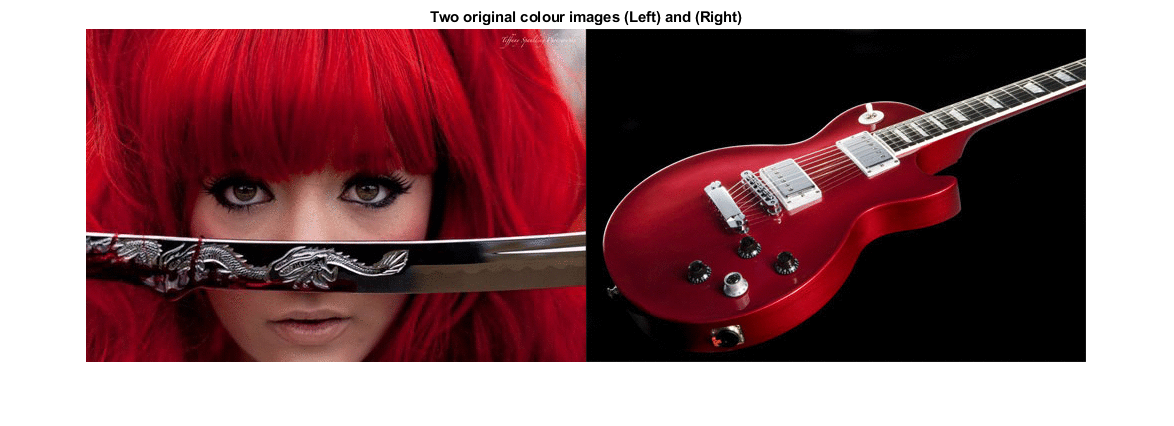



figure
imshowpair(Im1,Im2,'montage')
title('Two original colour images (Left) and (Right)');

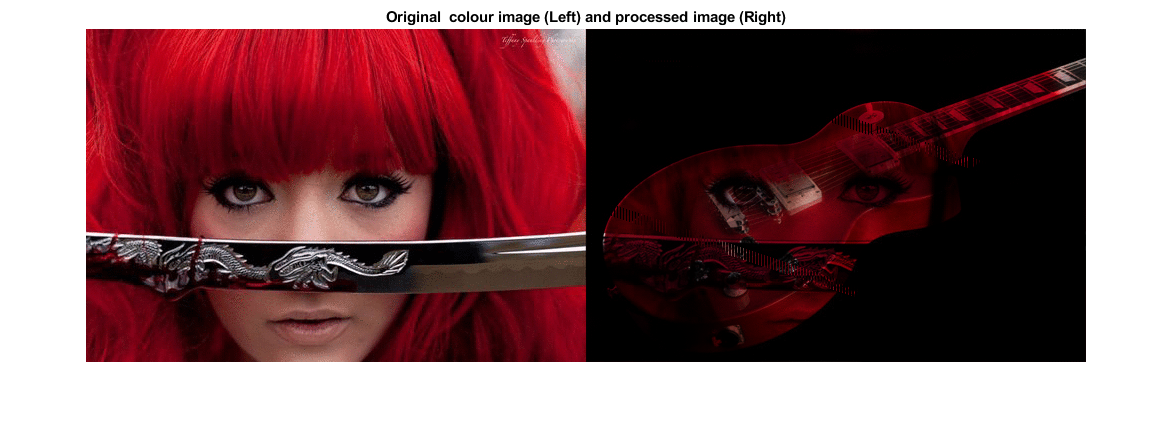


figure
imshowpair(Im1,K,'montage')
title('Original  colour image (Left) and processed image (Right)');